% Model Recovery
% estimate internal-external noise ratio by minimizing the calculated pA and estimated pA


addpath(genpath('Data_OOD'))
addpath(genpath('fxn_model'))
addpath(genpath('fxn_analysis_RC'))

clc
close all
%% simulation SETTING
truth.mu_PRS = 0.64; % mean of the internal variable distribution [PRS]
truth.sigma_PRS = 0.09; % std of the internal variable distribution [PRS], treated as 5he external noise
truth.mu_ABS = 0.53;
truth.sigma_ABS = 0.08;
ntrials_sim = 10000; % [simulation] num of trials simulated to generate the data set
truth.alpha_PRS = 1; % alpha_PRS; alpha_ABS is always prop. to alpha_PRS
truth.alpha_ABS = 1.5; % alpha_PRS; alpha_ABS is always prop. to alpha_PRS
truth.thresh =  0.6; % applied to the NON-standardized IV distirbution

 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
nB = 50; % number of bootstrapping
nrep = 10; % 30
truth.nparams_model = 3;

%% model fitting SETTING
options = optimoptions('fmincon','MaxIterations',5000,'Display','off');

% define the range
switch truth.nparams_model
    case 1
        params0 = .5;
        params_lb = 0;
        params_ub = 2;
    case 2
        params0 = [.5, 0];
        params_lb = [0, -1];
        params_ub = [2, 1];
    case 3
        params0 = [.5, .5, 0];
        params_lb = [0, 0, -1];
        params_ub = [3, 3, 2];
end

assert(truth.nparams_model == length(params_ub));

%% empty folders for all iterations
% simulation
IV_sim_allB = nan(nB, 2, ntrials_sim);
resp_sim_allB = IV_sim_allB;
metric_sim_allB = nan(nB, 8);

% estimated params
params_est_allB = nan(nB, truth.nparams_model);

% predictions
IV_pred_allB = nan(nB, 2, ntrials_sim);
resp_pred_allB = IV_sim_allB;
metric_pred_allB = nan(nB, 8);

%%
for iB = 1:nB
    %    simulation  %
    switch truth.nparams_model
        case 1, params_true = alpha;
        case 2, params_true = [alpha, truth.thresh];
        case 3, params_true = [truth.alpha_PRS, truth.alpha_ABS, truth.thresh];
    end
    
    sim = MR_sim(ntrials_sim, truth, params_true, 0);
    
    IV_sim_allB(iB, :, :) = sim.IV;    % nB x 2 ntrials_sim
    resp_sim_allB(iB, :, :) = sim.resp;    % nB x 2 ntrials_sim
    metric_sim_allB(iB, :) = sim.metrics_sim; % nB x 8 (dprime, criterion, pC, pHit, pFA, pA, pA_PRS, pA_ABS)
    
    %  model fitting  %
    fxn_estParams = @(params) fxn_getError(params, sim);
    
    problem_ML = createOptimProblem('fmincon','objective', fxn_estParams,'x0', params0, 'lb', params_lb, 'ub', params_ub, 'options',options);
    ms_ML = MultiStart('StartPointsToRun', 'bounds', 'Display', 'off', 'UseParallel',1);
    params_est = run(ms_ML, problem_ML, nrep);
    params_est_allB(iB, :) = params_est;
    
    %   Prediction  %
    pred = MR_pred(params_est, sim);
    metric_pred_allB(iB, :) = pred;
    
    if ~mod(iB, nB/10), fprintf('%d ',10-round(iB/nB*10)+1), end
end % end of ii

10 9 8 7 6 5 4 3 2 1 

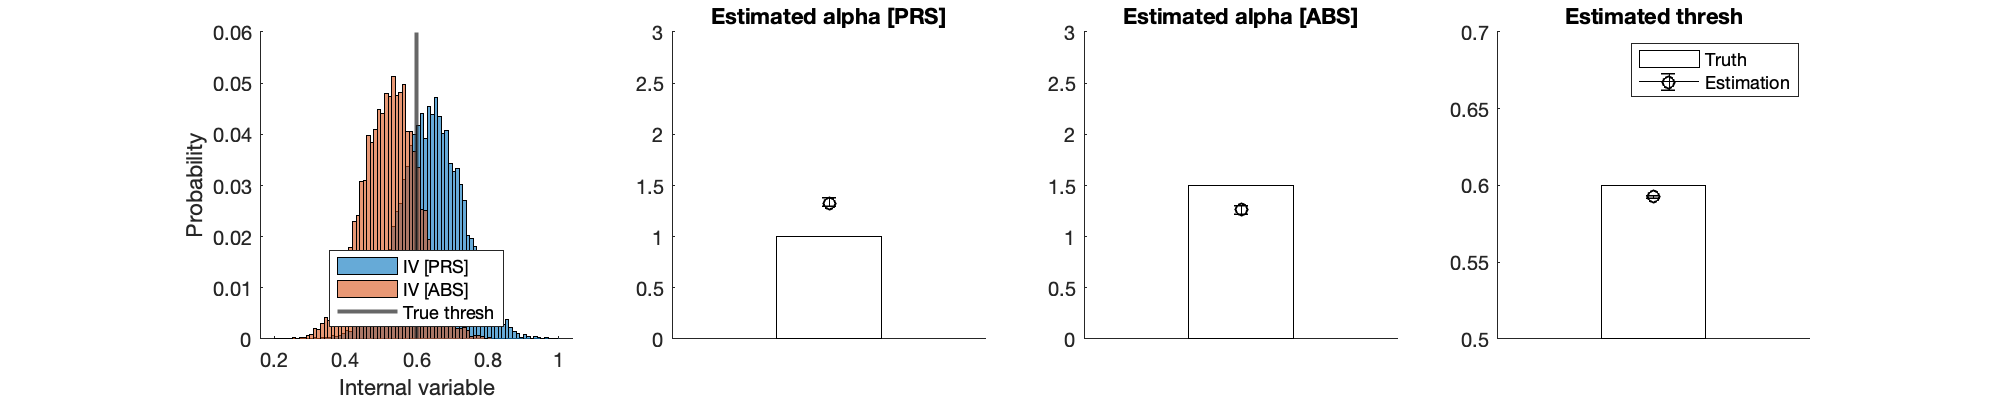

 
%%%%%%%%%%%%%%%%% plot %%%%%%%%%%%%%%%%%
figure('Position', [0 0 1000 200])

%%%%%%%%%%%%%%
% plot data %
%%%%%%%%%%%%%%
subplot(1,4,1), hold on
histogram(squeeze(IV_sim_allB(1,1,:)), 'Normalization', 'Probability')
histogram(squeeze(IV_sim_allB(1,2,:)), 'Normalization', 'Probability')
xline(params_true(3), 'linewidth', 2);
ylabel('Probability')
xlabel('Internal variable')
legend({'IV [PRS]','IV [ABS]','True thresh'},'Location','south')


%%%%%%%%%%%%%%%%%%%%%%%%%
% plot estimated params %
%%%%%%%%%%%%%%%%%%%%%%%%%
titles_paramsEST = {'alpha [PRS]', 'alpha [ABS]', 'thresh'};
% if truth.nparams_model == 3, np= 2; else, np = 1;end
for ip = 1:truth.nparams_model
    subplot(1,4, ip+1), hold on
    
    % true value
    bar(1, params_true(ip), 'FaceColor','w','EdgeColor','k');
    
    % estimation
    params_est = params_est_allB(:, ip);
    params_est_med = median(params_est);
    params_est_CI68 = quantile(params_est, [.16, .84]) ;
    errorbar(1, params_est_med, params_est_med-params_est_CI68(1), params_est_CI68(2)-params_est_med, 'ok-')
    
    xticks([]),xticklabels([])
    if ip ~= 3, ylim([0, 3]), else, ylim([truth.thresh-.1, truth.thresh+.1]), end
    if ip == 3, legend({'Truth', 'Estimation'}), end
    
    title(sprintf('Estimated %s', titles_paramsEST{ip}))
end

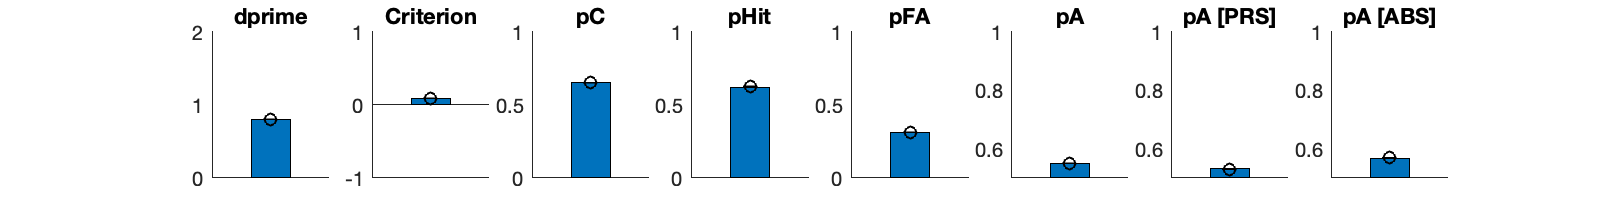


%%%%%%%%%%%%%%%%%%%%%%%%%%
% plot predicted metrics %
%%%%%%%%%%%%%%%%%%%%%%%%%%
figure('Position',[0 0 800 100])
titles_long = {'Sensitivity (d'')',  'Criterion', 'Proportion correct', 'Hit rate', 'False alarm rate', 'Prop. agreement', 'Prop. agreement [PRS]', 'Prop. agreement [ABS]'};
titles_short = {'dprime',  'Criterion', 'pC', 'pHit', 'pFA', 'pA', 'pA [PRS]', 'pA [ABS]'};
ylims = [0, 2; -1,1; 0,1;0,1;0,1;.5, 1;.5,1;.5,1];
for im = 1:8
    MR_plotPRED(im, titles_short{im} , metric_sim_allB(:,im), metric_pred_allB(:,im), ylims(im, :))
    xticks([]),xticklabels([])
end

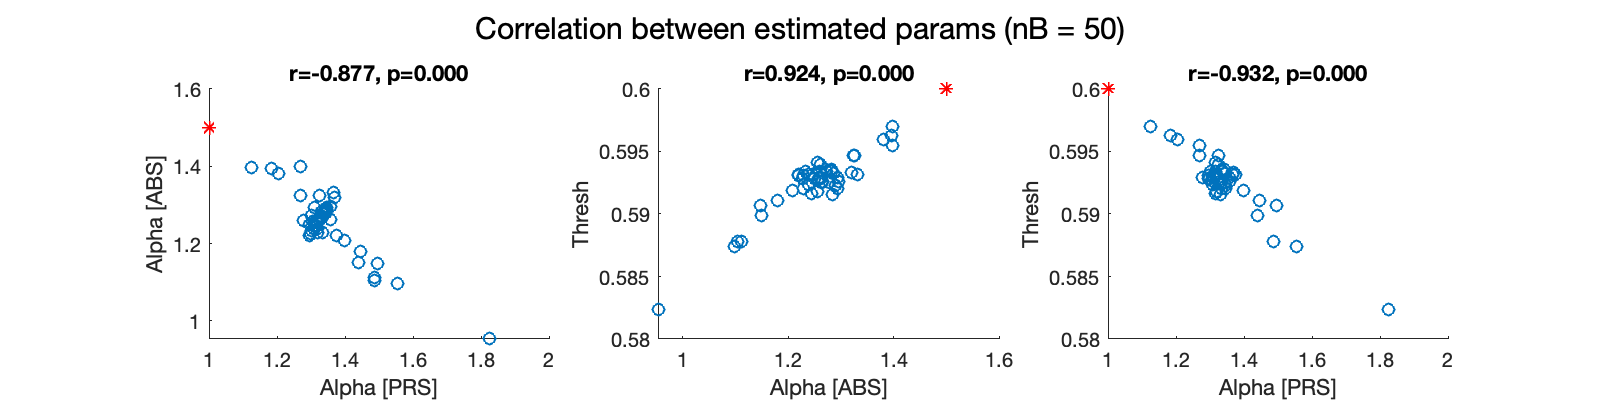



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure('Position',[0 0 800 200])
subplot(1,3,1), hold on
plot(params_est_allB(:,1), params_est_allB(:,2),'o')
plot(params_true(1),params_true(2), 'r*')
xlabel('Alpha [PRS]')
ylabel('Alpha [ABS]')
[r,p] = corr(params_est_allB(:,1), params_est_allB(:,2));
title(sprintf('r=%.3f, p=%.3f',r, p))

subplot(1,3,2), hold on
plot(params_est_allB(:,2), params_est_allB(:,3),'o')
plot(params_true(2),params_true(3), 'r*')
xlabel('Alpha [ABS]')
ylabel('Thresh')
[r,p] = corr(params_est_allB(:,2), params_est_allB(:,3));
title(sprintf('r=%.3f, p=%.3f',r, p))

subplot(1,3,3), hold on
plot(params_est_allB(:,1), params_est_allB(:,3),'o')
plot(params_true(1),params_true(3), 'r*')
xlabel('Alpha [PRS]')
ylabel('Thresh')
[r,p] = corr(params_est_allB(:,1), params_est_allB(:,3));
title(sprintf('r=%.3f, p=%.3f',r, p))

sgtitle(sprintf('Correlation between estimated params (nB = %d)', nB))

function MR_plotPRED(iplot, title_, data, pred, ylim_)

subplot(1,8,iplot), hold on

% get ave and CI
data_med = median(data);
pred_med = median(pred);
pred_CI68 = quantile(pred, [.16, .84]) ;

% plot
bar(1, data_med)
errorbar(1, pred_med, pred_med - pred_CI68(1), pred_CI68(2)-pred_med, 'ok')
ylim(ylim_)
title(title_)
end
